# 1: Load data and pool

So far, the scripts only used one experiment per time and only information from spontaneous spiking. From here on, I pooled all found putative RGC DREADDS from the different experiments. For simplicity, I continue with the same experiment but provide the code for pooling. 

At this pont, I need to introduce a new, pre-generated file: alignedBasicParameters. It is a Matlab cell array (*number of units x 202 cell array)* that stores the extracted parameters from the light responses. In my experiments, I used a battery of different stimuli but many of them are not used in this paper. However, this information is not lost and stored, in a compact way, in these cell arrays. Below is a figure that shows exemplary the way I extracted the informations (for more details, see Hilgen et al., 207 https://doi.org/10.1038/srep42330). Top left shows 30 responses (shown as spike rasters) of one RGC unit to a simple light ON/OFF stimulus. A peristimulus time histogram (PSTH) was calculated and parameters like the peak (A1 (for light ON), A2 (for OFF)), time to peak (T2P1, T2P2) and response duration (RD1, RD2). With these parameters it is possibble to characterise and, to some extend, group the different cell responses. For example, the Bias Index (BI, see below PSTH) can be calculated to define if a cell responds stronger to light ON (closer to 1 values) or OFF (closer to -1 values). In a same way these parameters can be extracted from the different components of a Chirp (see top right) and a moving stimulus (bottom right). For the latter one, it can be also calculated if the RGC is direction- or orientation-selective. The so-called DSI or OSI ranges between 0 (not DS/OS) and 1 (DS/OS)). All these parameters are used in the following to "pre group" the different types and prepare them for a final classification. 

In this script I don't provide information how alignedBasicParameters is created - it is very customised for my experimental setup and used stimuli. But I did put my old scripts to generate alignedBasicParameters in an extra folder to allow reproducibility. 

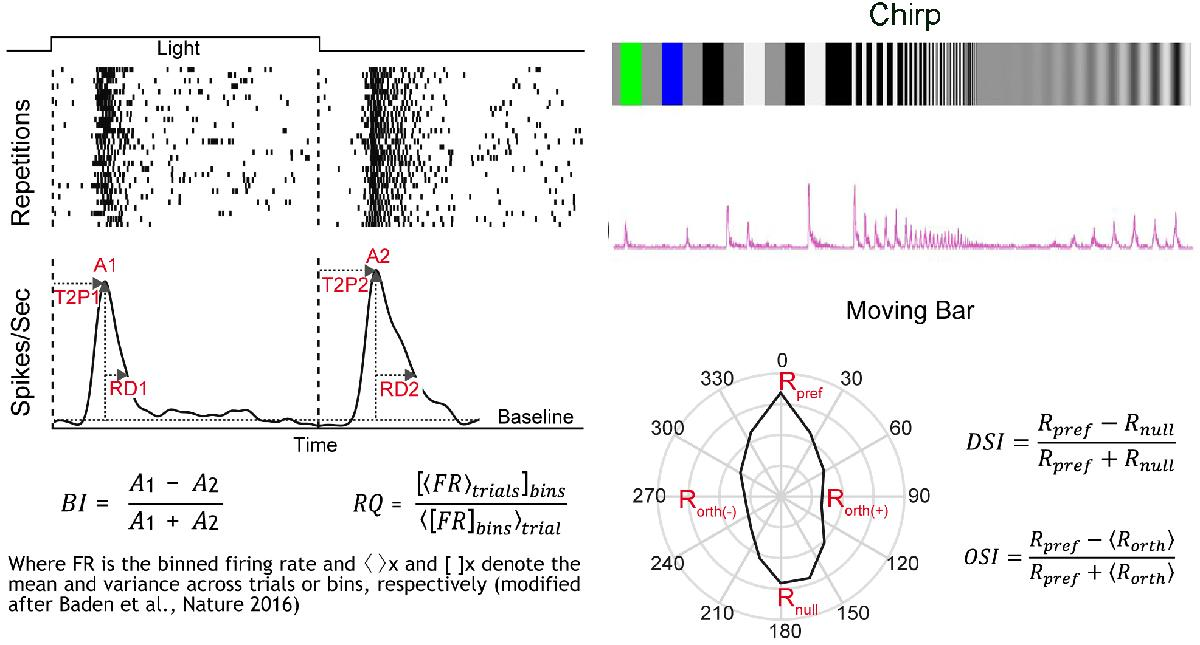

clear
% Main data folder (as in step 1 & 2)
datafolder = ['D:\Dropbox\Projects\Leverhulme\Leverhulmeproject_draft\Final\Resubmission\NewMatlabCode\ExampleData'];

% additional data folders - should have the same folder structure like our
% example and should contain the files described below. I use the same
% main folder example for this example but that can be changed. I had 5
% experiments but if you have less or more, please uncomment/copy new
% lines.

datafolder2 = ['D:\Dropbox\Projects\Leverhulme\Leverhulmeproject_draft\Final\Resubmission\NewMatlabCode\ExampleData'];
datafolder3 = ['D:\Dropbox\Projects\Leverhulme\Leverhulmeproject_draft\Final\Resubmission\NewMatlabCode\ExampleData'];
datafolder4 = ['D:\Dropbox\Projects\Leverhulme\Leverhulmeproject_draft\Final\Resubmission\NewMatlabCode\ExampleData'];
datafolder5 = ['D:\Dropbox\Projects\Leverhulme\Leverhulmeproject_draft\Final\Resubmission\NewMatlabCode\ExampleData'];

newoutfolder = strcat(datafolder, '\outfolder\pooled'); 
mkdir(newoutfolder)


% legend for the new parameters
clearvars temp_legend
temp_legend{1,1} = 'experiment id';
temp_legend{1,2} = 'x pos (cluster centre)';
temp_legend{1,3} = 'y pos (cluster centre)';
temp_legend{1,4} = 'cluster number';
temp_legend{1,5} = 'Chrip RQ';
temp_legend{1,6} = 'Chirp fano factor';
temp_legend{1,7} = 'Chirp spike count';
temp_legend{1,8} = 'Chirp spikes/sec';
temp_legend{1,9} = 'FC BI (full contrast bias index)';
temp_legend{1,10} = 'FCA1peak';
temp_legend{1,11} = 'FCA1time2p';
temp_legend{1,12} = 'FCA1tau';
temp_legend{1,13} = 'FCA2peak';
temp_legend{1,14} = 'FCA2time2p';
temp_legend{1,15} = 'FCA2tau';
temp_legend{1,16} = 'MB BI';
temp_legend{1,17} = 'MB RQ';
temp_legend{1,18} = 'MB fano factor';
temp_legend{1,19} = 'MB spike count';
temp_legend{1,20} = 'MB spikes/sec';
temp_legend{1,21} = 'WMB OI';
temp_legend{1,22} = 'WMB DI';
temp_legend{1,23} = 'BMB OI';
temp_legend{1,24} = 'BMB DI';


% data 1
load(strcat(datafolder,'\outfolder\final_approxdata.mat')); % load final approx files
% load alignedBasicParameters
load(strcat(datafolder,'\alignedBasicParameters_P139_24_09_19_Scnn1aGQ_right_short2019_ctl_clustered.mat')); 
clearvars temp idx temp2 
temp = cell2mat(alignedBasicParameters1(2:end,[4:6,11:15,17:22,62:66,68,69,113,114]));
idx = ismember(temp(:,3),final_approxdata(:,4));
temp2 = temp(idx,:);
data_legend = [approxdata_legend,temp_legend];
temp3(1:length(temp2(:,1)),1) = 1; % experiment id
data1 = [final_approxdata,temp3,temp2]; % change data name according to data

%%  data 2
load(strcat(datafolder,'\outfolder\final_approxdata.mat')); % load final approx files
%% load alignedBasicParameters
load(strcat(datafolder,'\alignedBasicParameters_P139_24_09_19_Scnn1aGQ_right_short2019_ctl_clustered.mat')); 
clearvars temp idx temp2 
temp = cell2mat(alignedBasicParameters1(2:end,[4:6,11:15,17:22,62:66,68,69,113,114]));
idx = ismember(temp(:,3),final_approxdata(:,4));
temp2 = temp(idx,:);
temp3(1:length(temp2(:,1)),1) = 2; % experiment id
data2 = [final_approxdata,temp3,temp2]; % change data name according to data

%%data 3
load(strcat(datafolder,'\outfolder\final_approxdata.mat')); % load final approx files
%%load alignedBasicParameters
load(strcat(datafolder,'\alignedBasicParameters_P139_24_09_19_Scnn1aGQ_right_short2019_ctl_clustered.mat')); 
clearvars temp idx temp2 
temp = cell2mat(alignedBasicParameters1(2:end,[4:6,11:15,17:22,62:66,68,69,113,114]));
idx = ismember(temp(:,3),final_approxdata(:,4));
temp2 = temp(idx,:);
temp3(1:length(temp2(:,1)),1) = 3; % experiment id
data3 = [final_approxdata,temp3,temp2]; % change data name according to data

%%data 4
load(strcat(datafolder,'\outfolder\final_approxdata.mat')); % load final approx files
%%load alignedBasicParameters
load(strcat(datafolder,'\alignedBasicParameters_P139_24_09_19_Scnn1aGQ_right_short2019_ctl_clustered.mat')); 
clearvars temp idx temp2 
temp = cell2mat(alignedBasicParameters1(2:end,[4:6,11:15,17:22,62:66,68,69,113,114]));
idx = ismember(temp(:,3),final_approxdata(:,4));
temp2 = temp(idx,:);
temp3(1:length(temp2(:,1)),1) = 4; % experiment id
data4 = [final_approxdata,temp3,temp2]; % change data name according to data

%%data 5
load(strcat(datafolder,'\outfolder\final_approxdata.mat')); % load final approx files
%%load alignedBasicParameters
load(strcat(datafolder,'\alignedBasicParameters_P139_24_09_19_Scnn1aGQ_right_short2019_ctl_clustered.mat')); 
clearvars temp idx temp2 
temp = cell2mat(alignedBasicParameters1(2:end,[4:6,11:15,17:22,62:66,68,69,113,114]));
idx = ismember(temp(:,3),final_approxdata(:,4));
temp2 = temp(idx,:);
temp3(1:length(temp2(:,1)),1) = 5; % experiment id
data5 = [final_approxdata,temp3,temp2]; % change data name according to data

pooldata = [data1;data2;data3;data4;data5]; % uncomment for pooling
% pooldata = [data1];
save(strcat(newoutfolder,'\pooldata.mat'),"pooldata", "data_legend")
disp('done loading data')

done loading data


# 2: DS/OS separation & Remove RQ units with < 25th prct of RQ

I am using the parameter RQ to remove noisy units (noisy units = RGCs which light responses seem random and not driven by light):

RQ = [〈FR〉trials]bins /〈[FR]bins〉trials. Where FR is the binned firing rate and 〈 〉x and [ ]x denote the mean and variance across trials or bins, respectively (modified after Baden et al., Nature 2016). The Fano Factor is another option (not used here). To estimate the cutoff threshold, I plot the RQ distribution per experiment and try to estimate - by using percentiles - the cutoff value. Further, I use a very mild threshold to get rid of only really bad units. NB we need to look at different RQs --> Chirp RQ for not motion sensitive cells (stationary) and Moving Bar RQ for cells tuned to motion (non stationary)

#### A: DS/OS separation 

The criteria to separate between stationary and non stationary is an arbitrary threshold of the commonly accepted threshold of 0.33 for the OSI and DSI (Rivlin-Etzion et al., 2012 doi: [10.1016/j.neuron.2012.08.041](https://dx.doi.org/10.1016%2Fj.neuron.2012.08.041))

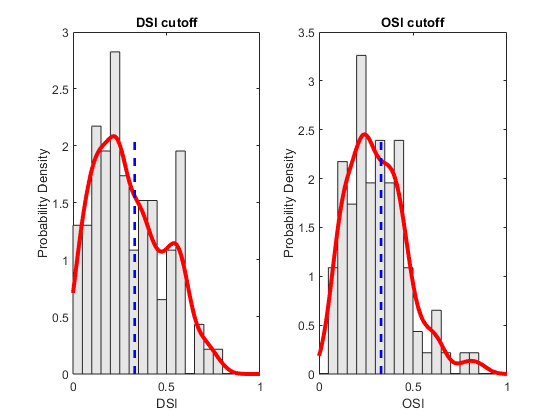

clearvars -except outfolder datafolder newoutfolder
load(strcat(newoutfolder,'\pooldata.mat'));
% load(strcat(newoutfolder,'\pooldata_test.mat')); % a dummy pooled data
% file

clearvars idx1 idx2 idx3
% if MB BI is higher than 0 than look at white MB DSI and OSI
idx1 = find(pooldata(:,27)>0 & (pooldata(:,32)>0.33 | pooldata(:,33)>0.33));
% if MB BI is smaller/equal than 0 than look at black MB DSI and OSI
idx2 = find(pooldata(:,27)<=0 & (pooldata(:,34)>0.33 | pooldata(:,35)>0.33));
idx3 = unique([idx1;idx2]);

nonstat_pooldata = pooldata(idx3,:);
pooldata(idx3,:) =[];
stat_pooldata = pooldata;
clearvars pooldata
load(strcat(newoutfolder,'\pooldata_test.mat'));

% DSI plot
clearvars mydata pdf_normmixture paramEsts xgrid pdfgrid minVal maxVal tmp3 pd
mydata = [pooldata(:,33);pooldata(:,35)];
%plot histogram with fit
mydata(isinf(mydata))=[];
div=0.05;
minVal = 0;
maxVal = 1;
bins = minVal:div:maxVal;
tmp3 = histcounts(mydata,bins);

subplot(1,2,1)
h = bar(bins(1:end-1),tmp3/(length(mydata)*div),'histc');
h.FaceColor = [.9 .9 .9];
pd = fitdist(mydata,'Kernel','Kernel','normal','Width', 0.05);
xgrid = linspace(minVal,maxVal,200);
pdfgrid = pdf(pd,xgrid);
hold on
plot(xgrid,pdfgrid,'-r','LineWidth',3)
hold on
clearvars x y
x = [0.33 0.33];
y = [0 max(pdfgrid)];
line(x,y,'Color','blue','LineStyle','--','LineWidth',2)
hold off
xlabel('DSI')
ylabel('Probability Density')
title('DSI cutoff')

clearvars mydata pdf_normmixture paramEsts xgrid pdfgrid minVal maxVal tmp3 pd
mydata = [pooldata(:,32);pooldata(:,34)];
%plot histogram with fit
mydata(isinf(mydata))=[];
div=0.05;
minVal = 0;
maxVal = 1;
bins = minVal:div:maxVal;
tmp3 = histcounts(mydata,bins);

subplot(1,2,2)
h = bar(bins(1:end-1),tmp3/(length(mydata)*div),'histc');
h.FaceColor = [.9 .9 .9];
pd = fitdist(mydata,'Kernel','Kernel','normal','Width', 0.05);
xgrid = linspace(minVal,maxVal,200);
pdfgrid = pdf(pd,xgrid);
hold on
plot(xgrid,pdfgrid,'-r','LineWidth',3)
hold on
clearvars x y
x = [0.33 0.33];
y = [0 max(pdfgrid)];
line(x,y,'Color','blue','LineStyle','--','LineWidth',2)
hold off
xlabel('OSI')
ylabel('Probability Density')
title('OSI cutoff')


save(strcat(newoutfolder,'\temp_pooldata.mat'),"stat_pooldata","nonstat_pooldata","data_legend")
disp('done DS/OS separation')

done DS/OS separation


#### B: Remove RQ units with < 25th prct of RQ

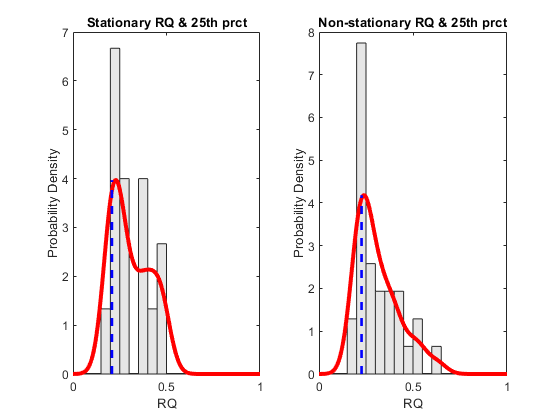

clearvars -except outfolder datafolder newoutfolder
load(strcat(newoutfolder,'\temp_pooldata.mat'));

% stat RQ
clearvars mydata pdf_normmixture paramEsts xgrid pdfgrid minVal maxVal tmp3 pd
mydata = stat_pooldata(:,16);
%plot histogram with fit
mydata(isinf(mydata))=[];
prc25_stat = prctile(mydata,25);
stat_pooldata(stat_pooldata(:,16)<prc25_stat,:)=[];
div=0.05;
minVal = 0;
maxVal = 1;
bins = minVal:div:maxVal;
tmp3 = histcounts(mydata,bins);

subplot(1,2,1)
h = bar(bins(1:end-1),tmp3/(length(mydata)*div),'histc');
h.FaceColor = [.9 .9 .9];
pd = fitdist(mydata,'Kernel','Kernel','normal','Width', 0.05);
xgrid = linspace(minVal,maxVal,200);
pdfgrid = pdf(pd,xgrid);
hold on
plot(xgrid,pdfgrid,'-r','LineWidth',3)
hold on
clearvars x y
x = [prc25_stat prc25_stat];
y = [0 max(pdfgrid)];
line(x,y,'Color','blue','LineStyle','--','LineWidth',2)
hold off
xlabel('RQ')
ylabel('Probability Density')
title('Stationary RQ & 25th prct')

% nonstat RQ
clearvars mydata pdf_normmixture paramEsts xgrid pdfgrid minVal maxVal tmp3 pd
mydata = nonstat_pooldata(:,28);
%plot histogram with fit
mydata(isinf(mydata))=[];
prc25_nonstat = prctile(mydata,25);
nonstat_pooldata(nonstat_pooldata(:,16)<prc25_nonstat,:)=[];
div=0.05;
minVal = 0;
maxVal = 1;
bins = minVal:div:maxVal;
tmp3 = histcounts(mydata,bins);

subplot(1,2,2)
h = bar(bins(1:end-1),tmp3/(length(mydata)*div),'histc');
h.FaceColor = [.9 .9 .9];
pd = fitdist(mydata,'Kernel','Kernel','normal','Width', 0.05);
xgrid = linspace(minVal,maxVal,200);
pdfgrid = pdf(pd,xgrid);
hold on
plot(xgrid,pdfgrid,'-r','LineWidth',3)
hold on
clearvars x y
x = [prc25_nonstat prc25_nonstat];
y = [0 max(pdfgrid)];
line(x,y,'Color','blue','LineStyle','--','LineWidth',2)
hold off
xlabel('RQ')
ylabel('Probability Density')
title('Non-stationary RQ & 25th prct')

save(strcat(newoutfolder,'\final_pooldata.mat'),"stat_pooldata","nonstat_pooldata","data_legend","prc25_nonstat","prc25_stat")
disp('done remove RQ units with < 25th prct of RQ')

done remove RQ units with < 25th prct of RQ


# 3: Write HDF files

Alright, the next part might seem not necessary if you are more familar with funneling Python code into Matlab. However, I took the detour to import the spikes from putative DREADD RGCs into Matlab, export them as Hdf5 files and run these filesin Python for SPIKE distance clustering (next step). That allowed me also to separate the stat and nonstat files which should result in better distinguishable clusters. As I wrote above, the data that we are going to analyse is light driven. Hence we need the spikes and corresponding information when and what image was shown (here called trigger file and protocol file). The protocol file (txt file) is in the folder while we need to load the Matlab trigger file. It contains several files: timeStampMatrix contains the time ponts when an image was displayed. timeStampMatrix divided by the sampling gives that timing in seconds. onsetsTime and onstesFrame give the timing of the first image from a new block of stimulus (see protocol file). 

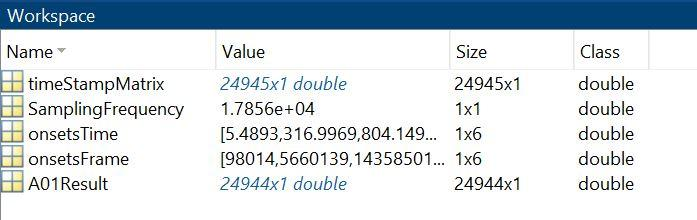

#### A: reshape/resetting the data

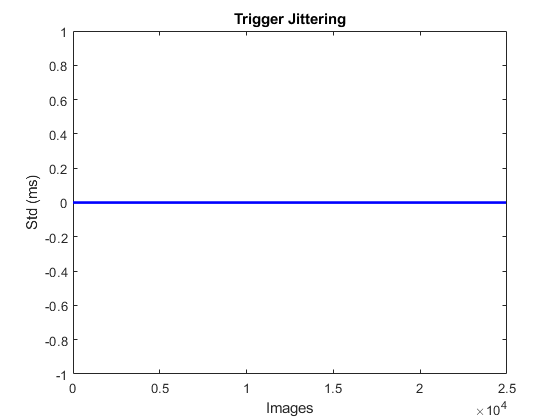

clearvars -except outfolder datafolder newoutfolder
load(strcat(newoutfolder,'\final_pooldata.mat'));

% data1
%%%%% set path %%%%%%
% load the trigger file
load(strcat(datafolder,'\Trigger_P139_24_09_19_Scnn1aGQ_right_short2019_ctl_Ch1_2.mat'));
% set the output file
TriggeroutFile = strcat(newoutfolder,'\Trigger_Scnn1a_data1.mat'); % change the name
% the hdf5 spikes file
hdf5file=(strcat(datafolder,'\P139_24_09_19_Scnn1aGQ_right_short2019_ctl_clustered.hdf5'));
% resetting triggers
clearvars TSorg test_TSM test_OF
TSorg = timeStampMatrix(1); % the time point when the stimulation starts
timeStampMatrix=(timeStampMatrix-TSorg)+1; % reset everything to start at 1
test_TSM(1,:) =timeStampMatrix; % for alignment testing
onsetsFrame =(onsetsFrame-TSorg(1))+1; % same here
test_OF(1,:) =onsetsFrame; % for alignment testing
onsetsTime = (onsetsTime-(onsetsFrame(1)+1)/SamplingFrequency);
% export the resetted timeStampMatrix
save(char(TriggeroutFile),'timeStampMatrix', 'onsetsFrame','A01Result','onsetsTime', 'SamplingFrequency')
% stat units
clearvars mydata 
mydata = stat_pooldata(stat_pooldata(:,12)==1,:); % experiment id
[stat_shapes1,stat_times1,stat_centres1,stat_cluster_id1,stat_data1] = g_writeHDF5reshaper(hdf5file,mydata,TSorg);
% nonstat units
clearvars mydata 
mydata = nonstat_pooldata(nonstat_pooldata(:,12)==1,:); % experiment id
[nonstat_shapes1,nonstat_times1,nonstat_centres1,nonstat_cluster_id1,nonstat_data1] = g_writeHDF5reshaper(hdf5file,mydata,TSorg);


% data2
%%%%% set path %%%%%%
% load the trigger file
load(strcat(datafolder,'\Trigger_P139_24_09_19_Scnn1aGQ_right_short2019_ctl_Ch1_2.mat'));
% set the output file
TriggeroutFile = strcat(newoutfolder,'\Trigger_Scnn1a_data2.mat'); %%%%%%%%%% change the name
% the hdf5 spikes file
hdf5file=(strcat(datafolder,'\P139_24_09_19_Scnn1aGQ_right_short2019_ctl_clustered.hdf5'));
% resetting triggers
clearvars TSorg 
TSorg = timeStampMatrix(1); % the time point when the stimulation starts
timeStampMatrix=(timeStampMatrix-TSorg)+1; % reset everything to start at 1
test_TSM(2,:) =timeStampMatrix; % for alignment testing
onsetsFrame =(onsetsFrame-TSorg(1))+1; % same here
test_OF(2,:) =onsetsFrame; % for alignment testing
onsetsTime = (onsetsTime-(onsetsFrame(1)+1)/SamplingFrequency);
% export the resetted timeStampMatrix
save(char(TriggeroutFile),'timeStampMatrix', 'onsetsFrame','A01Result','onsetsTime', 'SamplingFrequency')
% stat units
clearvars mydata 
%%%% change experiment id
mydata = stat_pooldata(stat_pooldata(:,12)==2,:); 
[stat_shapes2,stat_times2,stat_centres2,stat_cluster_id2,stat_data2] = g_writeHDF5reshaper(hdf5file,mydata,TSorg);
stat_cluster_id2 = stat_cluster_id2 + stat_cluster_id1(end); % to avoid double naming of clusters
% nonstat units
%%%% change experiment id
clearvars mydata 
mydata = nonstat_pooldata(nonstat_pooldata(:,12)==2,:); 
[nonstat_shapes2,nonstat_times2,nonstat_centres2,nonstat_cluster_id2,nonstat_data2] = g_writeHDF5reshaper(hdf5file,mydata,TSorg);
nonstat_cluster_id2 = nonstat_cluster_id2 + nonstat_cluster_id1(end); % to avoid double naming of clusters


% data3
%%%%% set path %%%%%%
% load the trigger file
load(strcat(datafolder,'\Trigger_P139_24_09_19_Scnn1aGQ_right_short2019_ctl_Ch1_2.mat'));
% set the output file
TriggeroutFile = strcat(newoutfolder,'\Trigger_Scnn1a_data3.mat'); %%%%%%%%%% change the name
% the hdf5 spikes file
hdf5file=(strcat(datafolder,'\P139_24_09_19_Scnn1aGQ_right_short2019_ctl_clustered.hdf5'));
% resetting triggers
clearvars TSorg 
TSorg = timeStampMatrix(1); % the time point when the stimulation starts
timeStampMatrix=(timeStampMatrix-TSorg)+1; % reset everything to start at 1
test_TSM(3,:) =timeStampMatrix; % for alignment testing
onsetsFrame =(onsetsFrame-TSorg(1))+1; % same here
test_OF(3,:) =onsetsFrame; % for alignment testing
onsetsTime = (onsetsTime-(onsetsFrame(1)+1)/SamplingFrequency);
% export the resetted timeStampMatrix
save(char(TriggeroutFile),'timeStampMatrix', 'onsetsFrame','A01Result','onsetsTime', 'SamplingFrequency')
% stat units
clearvars mydata 
%%%% change experiment id
mydata = stat_pooldata(stat_pooldata(:,12)==3,:); 
[stat_shapes3,stat_times3,stat_centres3,stat_cluster_id3,stat_data3] = g_writeHDF5reshaper(hdf5file,mydata,TSorg);
stat_cluster_id3 = stat_cluster_id3 + stat_cluster_id2(end); % to avoid double naming of clusters
% nonstat units
%%%% change experiment id
clearvars mydata 
mydata = nonstat_pooldata(nonstat_pooldata(:,12)==3,:); 
[nonstat_shapes3,nonstat_times3,nonstat_centres3,nonstat_cluster_id3,nonstat_data3] = g_writeHDF5reshaper(hdf5file,mydata,TSorg);
nonstat_cluster_id3 = nonstat_cluster_id3 + nonstat_cluster_id2(end); % to avoid double naming of clusters

% data4
%%%%% set path %%%%%%
% load the trigger file
load(strcat(datafolder,'\Trigger_P139_24_09_19_Scnn1aGQ_right_short2019_ctl_Ch1_2.mat'));
% set the output file
TriggeroutFile = strcat(newoutfolder,'\Trigger_Scnn1a_data4.mat'); %%%%%%%%%% change the name
% the hdf5 spikes file
hdf5file=(strcat(datafolder,'\P139_24_09_19_Scnn1aGQ_right_short2019_ctl_clustered.hdf5'));
% resetting triggers
clearvars TSorg 
TSorg = timeStampMatrix(1); % the time point when the stimulation starts
timeStampMatrix=(timeStampMatrix-TSorg)+1; % reset everything to start at 1
test_TSM(4,:) =timeStampMatrix; % for alignment testing
onsetsFrame =(onsetsFrame-TSorg(1))+1; % same here
test_OF(4,:) =onsetsFrame; % for alignment testing
onsetsTime = (onsetsTime-(onsetsFrame(1)+1)/SamplingFrequency);
% export the resetted timeStampMatrix
save(char(TriggeroutFile),'timeStampMatrix', 'onsetsFrame','A01Result','onsetsTime', 'SamplingFrequency')
% stat units
clearvars mydata 
%%%% change experiment id
mydata = stat_pooldata(stat_pooldata(:,12)==4,:); 
[stat_shapes4,stat_times4,stat_centres4,stat_cluster_id4,stat_data4] = g_writeHDF5reshaper(hdf5file,mydata,TSorg);
stat_cluster_id4 = stat_cluster_id4 + stat_cluster_id3(end); % to avoid double naming of clusters
% nonstat units
%%%% change experiment id
clearvars mydata 
mydata = nonstat_pooldata(nonstat_pooldata(:,12)==4,:); 
[nonstat_shapes4,nonstat_times4,nonstat_centres4,nonstat_cluster_id4,nonstat_data4] = g_writeHDF5reshaper(hdf5file,mydata,TSorg);
nonstat_cluster_id4 = nonstat_cluster_id4 + nonstat_cluster_id3(end); % to avoid double naming of clusters


% data5
%%%%% set path %%%%%%
% load the trigger file
load(strcat(datafolder,'\Trigger_P139_24_09_19_Scnn1aGQ_right_short2019_ctl_Ch1_2.mat'));
% set the output file
TriggeroutFile = strcat(newoutfolder,'\Trigger_Scnn1a_data5.mat'); %%%%%%%%%% change the name
% the hdf5 spikes file
hdf5file=(strcat(datafolder,'\P139_24_09_19_Scnn1aGQ_right_short2019_ctl_clustered.hdf5'));
% resetting triggers
clearvars TSorg 
TSorg = timeStampMatrix(1); % the time point when the stimulation starts
timeStampMatrix=(timeStampMatrix-TSorg)+1; % reset everything to start at 1
test_TSM(5,:) =timeStampMatrix; % for alignment testing
onsetsFrame =(onsetsFrame-TSorg(1))+1; % same here
test_OF(5,:) =onsetsFrame; % for alignment testing
onsetsTime = (onsetsTime-(onsetsFrame(1)+1)/SamplingFrequency);
% export the resetted timeStampMatrix
save(char(TriggeroutFile),'timeStampMatrix', 'onsetsFrame','A01Result','onsetsTime', 'SamplingFrequency')
% stat units
clearvars mydata 
%%%% change experiment id
mydata = stat_pooldata(stat_pooldata(:,12)==5,:); 
[stat_shapes5,stat_times5,stat_centres5,stat_cluster_id5,stat_data5] = g_writeHDF5reshaper(hdf5file,mydata,TSorg);
stat_cluster_id5 = stat_cluster_id5 + stat_cluster_id4(end); % to avoid double naming of clusters
% nonstat units
%%%% change experiment id
clearvars mydata 
mydata = nonstat_pooldata(nonstat_pooldata(:,12)==5,:); 
[nonstat_shapes5,nonstat_times5,nonstat_centres5,nonstat_cluster_id5,nonstat_data5] = g_writeHDF5reshaper(hdf5file,mydata,TSorg);
nonstat_cluster_id5 = nonstat_cluster_id5 + nonstat_cluster_id4(end); % to avoid double naming of clusters



% testing the jittering of the different triggers
% normally the triggers are stable - NB the std is looking at data
% points that were aquired with ~ 18 points per milisecond!!! - hence I
% plotted the milisecond variance on the Y axis. There are ways to correct
% such jittering (e.g fit the variance, apply function to time stamps). Why
% is that important? In the next step we look at spike train similarities
% and we need to have a low jittering between the experiments
close(gcf)
lt = length(test_TSM(:,1));
for i = 1:length(test_TSM(1,:))
    test_TSM(6,i) = std(test_TSM(1:lt,i))/(SamplingFrequency/1000);
    test_TSM(7,i) = round(nanmean(test_TSM(1:lt,i)));
end
plot(test_TSM(6,:),'Color','blue','LineWidth',2)
xlabel('Images')
ylabel('Std (ms)')
title('Trigger Jittering')

timeStampMatrix = test_TSM(7,:);
lt = length(test_OF(:,1));
for i = 1:length(test_OF(1,:))
    test_OF(6,i) = std(test_OF(1:lt,i))/(SamplingFrequency/1000);
    test_OF(7,i) = round(nanmean(test_OF(1:lt,i)));
end
onsetsFrame = test_OF(7,:);
onsetsTimes = test_OF(7,:)/SamplingFrequency;
save(char(strcat(newoutfolder,'\Trigger_Scnn1a_mean.mat')),'timeStampMatrix', 'onsetsFrame','A01Result','onsetsTime', 'SamplingFrequency')



#### B: make stationary hdf5 files

%% make stat hdf
clearvars centres cluster_id times data shapes
% shapes = [stat_shapes1];
% times = [stat_times1];
% centres = [stat_centres1];
% cluster_id = [stat_cluster_id1];
% data = [stat_data1];

%%%% uncomment for pooled data
shapes = [stat_shapes1;stat_shapes2;stat_shapes3;stat_shapes4;stat_shapes5];
times = [stat_times1;stat_times2;stat_times3;stat_times4;stat_times5];
centres = [stat_centres1,stat_centres2,stat_centres3,stat_centres4,stat_centres5];
cluster_id = [stat_cluster_id1;stat_cluster_id2;stat_cluster_id3;stat_cluster_id4;stat_cluster_id5];
data = [stat_data1;stat_data2;stat_data3;stat_data4;stat_data5];
clearvars tmp 
tmp=unique(cluster_id);
for i = 1:length(tmp)
    cluster_id(cluster_id==tmp(i))=i-1;
end


[R, C] = sort(cluster_id);
cluster_id = R;
times = times(C);
data = data(C,:);
shapes = shapes(C,:);

Sampling = SamplingFrequency;
%%%%%%%%%% change name
% FILE=strcat(newoutfolder,'\singleHDF5_Scnn1a_stat.hdf5');
FILE=strcat(newoutfolder,'\pooledHDF5_Scnn1a_stat.hdf5');
DATASET1='centres'; %float64, xy position, cluster unit (see channelsNames)
DATASET2='cluster_id'; %int64
DATASET3='times'; %int32,

DATASET4='Sampling'; %float64, Sampling Rate
DATASET5='data';
DATASET6='shapes';%H5T_FLOAT H5T_IEEE_F64LE,  

file = H5F.create (FILE,'H5F_ACC_TRUNC','H5P_DEFAULT','H5P_DEFAULT');

dat1sizeID=H5S.create_simple(2,fliplr(size(centres)),[]);
dset1 = H5D.create (file, DATASET1, 'H5T_IEEE_F64LE', dat1sizeID, 'H5P_DEFAULT');

dat2sizeID=H5S.create_simple(1,length(cluster_id),[]);
dset2 = H5D.create (file, DATASET2, 'H5T_STD_I64LE', dat2sizeID, 'H5P_DEFAULT');

dat3sizeID=H5S.create_simple(1,length(times),[]);
dset3 = H5D.create (file, DATASET3, 'H5T_STD_I32LE', dat3sizeID, 'H5P_DEFAULT');

dat4sizeID=H5S.create_simple(2,fliplr(size(Sampling)),[]);
dset4 = H5D.create (file, DATASET4, 'H5T_IEEE_F64LE', dat4sizeID, 'H5P_DEFAULT');

dat5sizeID=H5S.create_simple(2,fliplr(size(data)),[]);
dset5 = H5D.create (file, DATASET5, 'H5T_IEEE_F64LE', dat5sizeID, 'H5P_DEFAULT');

dat6sizeID=H5S.create_simple(2,fliplr(size(shapes)),[]);
dset6 = H5D.create (file, DATASET6, 'H5T_STD_I32LE', dat6sizeID, 'H5P_DEFAULT');

H5D.write(dset1,'H5T_IEEE_F64LE','H5S_ALL','H5S_ALL','H5P_DEFAULT',centres);
H5D.write(dset2,'H5T_STD_I64LE','H5S_ALL','H5S_ALL','H5P_DEFAULT',int64(cluster_id));
H5D.write(dset3,'H5T_STD_I32LE','H5S_ALL','H5S_ALL','H5P_DEFAULT',int32(times));
H5D.write(dset4,'H5T_IEEE_F64LE','H5S_ALL','H5S_ALL','H5P_DEFAULT',Sampling);
H5D.write(dset5,'H5T_IEEE_F64LE','H5S_ALL','H5S_ALL','H5P_DEFAULT',double(data));
H5D.write(dset6,'H5T_STD_I32LE','H5S_ALL','H5S_ALL','H5P_DEFAULT',int32(shapes));

H5S.close(dat1sizeID);
H5S.close(dat2sizeID);
H5S.close(dat3sizeID);
H5S.close(dat4sizeID);
H5S.close(dat5sizeID);
H5S.close(dat6sizeID);
H5D.close(dset1);
H5D.close(dset2);
H5D.close(dset3);
H5D.close(dset4);
H5D.close(dset5);
H5D.close(dset6);
H5F.close(file);

(disp('done writing stat hdf5'))

done writing stat hdf5


#### C: make nonstationary hdf5 files

%% make stat hdf
clearvars centres cluster_id times data shapes
% shapes = [nonstat_shapes1];
% times = [nonstat_times1];
% centres = [nonstat_centres1];
% cluster_id = [nonstat_cluster_id1];
% data = [nonstat_data1];
shapes = [nonstat_shapes1;nonstat_shapes2;nonstat_shapes3;nonstat_shapes4;nonstat_shapes5];
times = [nonstat_times1;nonstat_times2;nonstat_times3;nonstat_times4;nonstat_times5];
centres = [nonstat_centres1,nonstat_centres2,nonstat_centres3,nonstat_centres4,nonstat_centres5];
cluster_id = [nonstat_cluster_id1;nonstat_cluster_id2;nonstat_cluster_id3;nonstat_cluster_id4;nonstat_cluster_id5];
data = [nonstat_data1;nonstat_data2;nonstat_data3;nonstat_data4;nonstat_data5];
clearvars tmp 
tmp=unique(cluster_id);
for i = 1:length(tmp)
    cluster_id(cluster_id==tmp(i))=i-1;
end

[R, C] = sort(cluster_id);
cluster_id = R;
times = times(C);
data = data(C,:);
shapes = shapes(C,:);

Sampling = SamplingFrequency;
%%%%%%%%%% change name
% FILE=strcat(newoutfolder,'\singleHDF5_Scnn1a_nonstat.hdf5');
FILE=strcat(newoutfolder,'\pooledHDF5_Scnn1a_nonstat.hdf5');
DATASET1='centres'; %float64, xy position, cluster unit (see channelsNames)
DATASET2='cluster_id'; %int64
DATASET3='times'; %int32,

DATASET4='Sampling'; %float64, Sampling Rate
DATASET5='data';
DATASET6='shapes';%H5T_FLOAT H5T_IEEE_F64LE,  

file = H5F.create (FILE,'H5F_ACC_TRUNC','H5P_DEFAULT','H5P_DEFAULT');

dat1sizeID=H5S.create_simple(2,fliplr(size(centres)),[]);
dset1 = H5D.create (file, DATASET1, 'H5T_IEEE_F64LE', dat1sizeID, 'H5P_DEFAULT');

dat2sizeID=H5S.create_simple(1,length(cluster_id),[]);
dset2 = H5D.create (file, DATASET2, 'H5T_STD_I64LE', dat2sizeID, 'H5P_DEFAULT');

dat3sizeID=H5S.create_simple(1,length(times),[]);
dset3 = H5D.create (file, DATASET3, 'H5T_STD_I32LE', dat3sizeID, 'H5P_DEFAULT');

dat4sizeID=H5S.create_simple(2,fliplr(size(Sampling)),[]);
dset4 = H5D.create (file, DATASET4, 'H5T_IEEE_F64LE', dat4sizeID, 'H5P_DEFAULT');

dat5sizeID=H5S.create_simple(2,fliplr(size(data)),[]);
dset5 = H5D.create (file, DATASET5, 'H5T_IEEE_F64LE', dat5sizeID, 'H5P_DEFAULT');

dat6sizeID=H5S.create_simple(2,fliplr(size(shapes)),[]);
dset6 = H5D.create (file, DATASET6, 'H5T_STD_I32LE', dat6sizeID, 'H5P_DEFAULT');

H5D.write(dset1,'H5T_IEEE_F64LE','H5S_ALL','H5S_ALL','H5P_DEFAULT',centres);
H5D.write(dset2,'H5T_STD_I64LE','H5S_ALL','H5S_ALL','H5P_DEFAULT',int64(cluster_id));
H5D.write(dset3,'H5T_STD_I32LE','H5S_ALL','H5S_ALL','H5P_DEFAULT',int32(times));
H5D.write(dset4,'H5T_IEEE_F64LE','H5S_ALL','H5S_ALL','H5P_DEFAULT',Sampling);
H5D.write(dset5,'H5T_IEEE_F64LE','H5S_ALL','H5S_ALL','H5P_DEFAULT',double(data));
H5D.write(dset6,'H5T_STD_I32LE','H5S_ALL','H5S_ALL','H5P_DEFAULT',int32(shapes));

H5S.close(dat1sizeID);
H5S.close(dat2sizeID);
H5S.close(dat3sizeID);
H5S.close(dat4sizeID);
H5S.close(dat5sizeID);
H5S.close(dat6sizeID);
H5D.close(dset1);
H5D.close(dset2);
H5D.close(dset3);
H5D.close(dset4);
H5D.close(dset5);
H5D.close(dset6);
H5F.close(file);
(disp('done writing nonstat hdf5'))

done writing nonstat hdf5


# 4: Conclusion

Nex, SPIKE distance calculating. that script will Jupyter Notebook